Read test images.

img_lenna=imread("Lenna.jpg");

Inner function implementation.

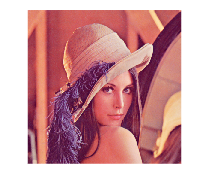

I1 = impyramid(img_lenna, 'reduce');
I2 = impyramid(I1, 'reduce');
I3 = impyramid(I2, 'reduce');
figure, imshow(img_lenna)

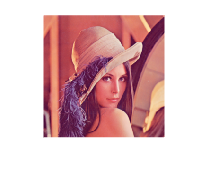

figure, imshow(I1)

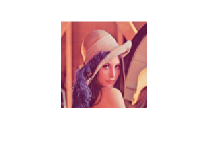

figure, imshow(I2)

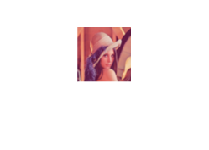

figure, imshow(I3)

Generate the image pyramid.

[g_pyramid,l_pyramid]=generate_gaussian_pyramid(img_lenna)

g_pyramid = 7×1 cell 数组
    {512×512×3 uint8}
    {256×256×3 uint8}
    {128×128×3 uint8}
    { 64×64×3  uint8}
    { 32×32×3  uint8}
    { 16×16×3  uint8}
    {  8×8×3   uint8}


l_pyramid = 7×1 cell 数组
    {512×512×3 uint8}
    {256×256×3 uint8}
    {128×128×3 uint8}
    { 64×64×3  uint8}
    { 32×32×3  uint8}
    { 16×16×3  uint8}
    {  8×8×3   uint8}


g_pyramid_concat=concatenate_image_pyramid(g_pyramid,2);
l_pyramid_concat=concatenate_image_pyramid(l_pyramid,2)

l_pyramid_concat = 512×770×3 uint8 数组
l_pyramid_concat(:,:,1) =

     0     1     0     0     1     0     1     0     0     0     2     0     0     2     0     0     0     0     0     0     0     0     2     0     0     0     1     3     0     0     0     1     1     0     2     0     0     0     0     1     0     1     0     0     0     3     0     0     2     3     0     0     0     0     2     1     1     0     2     1     0     6     0     0     0     2     0     0     0     0     5     0     1     0     0     0     1     0     0     3     0     0     0     1     0     0     0     3     0     0     0     0     3     0     0     1     0     2     2     0     0     0     2     1     0     1     0     0     0     0     3     1     0     5     0     0     1     1     0     2     2     0     4     0     0     3     0     1     0     1     3     0     0     1     0     1     0     2     0     1     2     0     0     1     0     2     0     0     0     0     1     0     2     0     1     

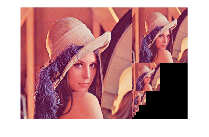

figure,imshow(g_pyramid_concat)

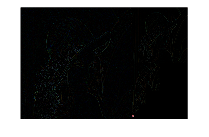

figure,imshow(l_pyramid_concat)

% display_image_pyramid(g_pyramid,2)

Implement the functions manually.

function [g_pyramid,l_pyramid]=generate_gaussian_pyramid(img)
    [m,n,c]=size(img);
    max_n=log2(m)-3;
    g_pyramid={img};
    for i=1:max_n
        gaussian_kernel = fspecial('gaussian', [5 5], 2);
        img_blur=imfilter(img,gaussian_kernel,"replicate","same","conv");
        l_pyramid(i,:)={img-img_blur};
        img=imresize(img_blur,0.5,"nearest");
        g_pyramid(i+1,:)={img};
    end
    l_pyramid(max_n+1,:)={img};
end

function display_image_pyramid(imgs,margin)

    N=size(imgs,1);
    
    canvas=concatenate_image_pyramid(imgs,margin);
    
    figure;
    for i=1:N
        subplot(2, N, i);
        imshow(imgs{i});
        title(size(imgs{i},1));
    end
    subplot(2,N,[N+1, N*2]);
    imshow(canvas);

end

function canvas=concatenate_image_pyramid(imgs,margin)

    [m,n,c]=size(imgs{1});
    canvas=zeros([m ceil(n*1.5+margin) c],"uint8");
    canvas(1:m,1:n,1:c)=imgs{1};

    pm=1;
    pn=n+1+margin;
    for i=2:size(imgs,1)
        [m,n,c]=size(imgs{i});
        canvas(pm:pm+m-1,pn:pn+n-1,1:c)=imgs{i};
        pm=pm+m;
    end

end


